# **Mesh**

Mesh object 

 Standard construction :

**mesh = Mesh(domain,h) **where domain is a Domain object and h is the requested mesh resolution. 

**mesh = Mesh(domain,h,h_bound) **where h_bound is the requested mesh resolution at the bounary. 

## **1. Basic use**

To create a Mesh object form a domain object

domain = Domain('square');

just run

mesh = Mesh(domain,0.1);

building mesh
done


then check the result

mesh.disp;

  Mesh with properties:

           domain: [1×1 Domain]
          h_input: 0.1000
            nodes: [175×2 double]
            edges: [40×3 double]
        triangles: [308×3 double]
    building_time: 0.0795



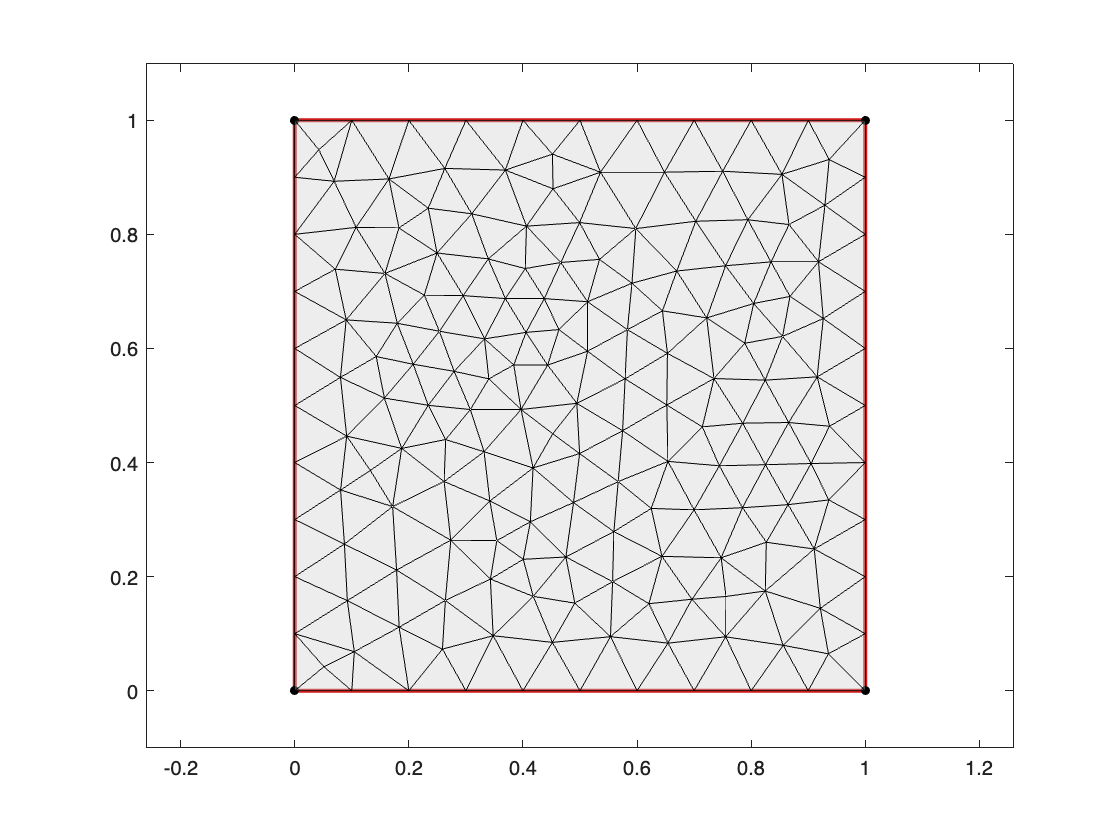

mesh.plot;

You can recover the nodes and the triangles with

mesh.nodes

ans =          0         0
    0.1000         0
    0.2000         0
    0.3000         0
    0.4000         0
    0.5000         0
    0.6000         0
    0.7000         0
    0.8000         0
    0.9000         0


mesh.triangles

ans =     81   116    33
    30    45   116
    35   103   126
   137    87    48
    37    75   119
   100     8     9
   115     2     3
    96    57    80
    77     6     7
   145    16   105


If needed you can specify the mesh resolution at the boundary: 

h = 0.1;
h_bound = 0.01;
mesh = Mesh(domain,h,h_bound);

building mesh
done


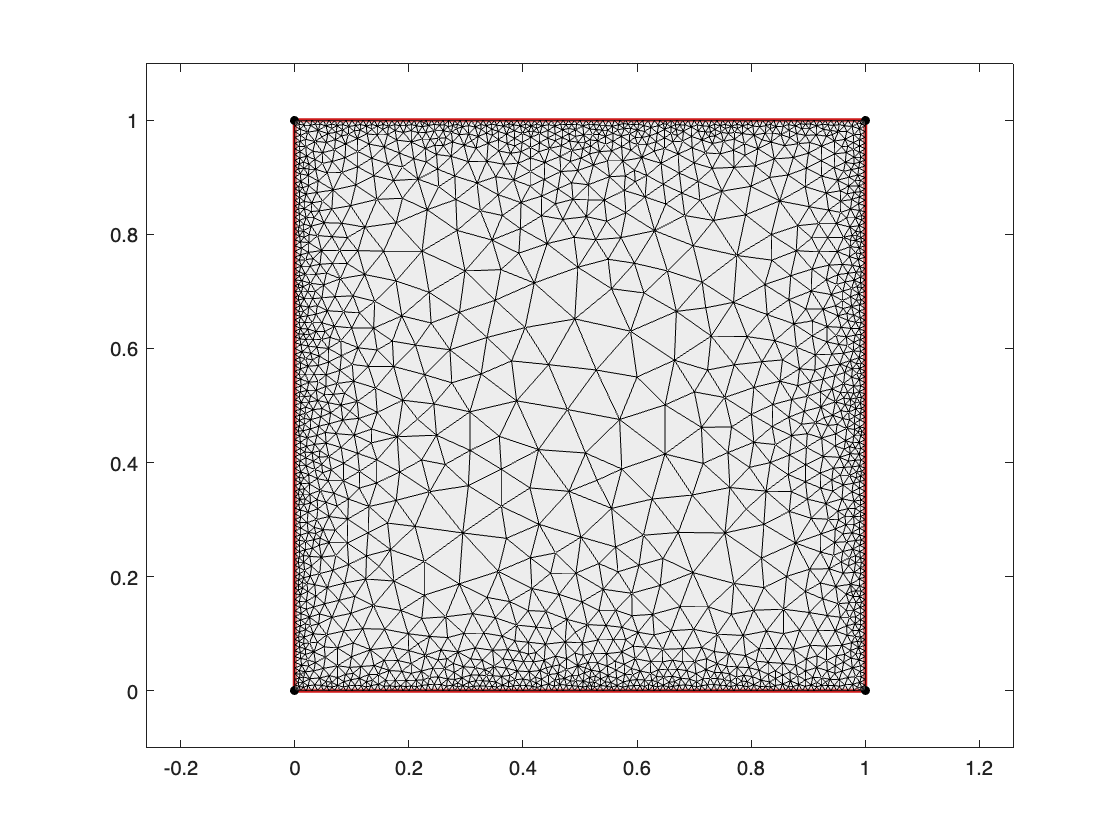

mesh.plot;

## **2. Example of meshes**

**Disc**

mesh = Mesh('disc',3,0.5);

building mesh
done


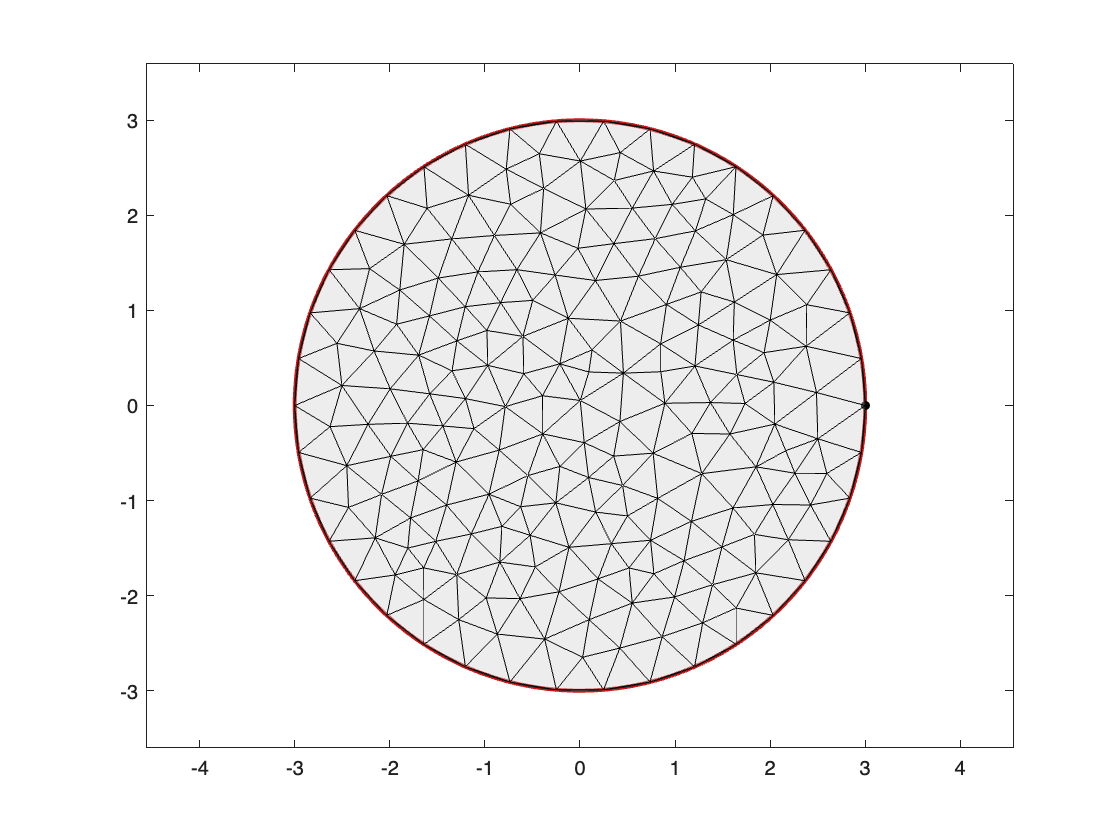

mesh.plot;

**Polygon**

nodes = [0 0; 2 0; 2 1;1 1;1 2;0 2];
domain = Domain(nodes);
mesh = Mesh(domain,0.1);

building mesh
done


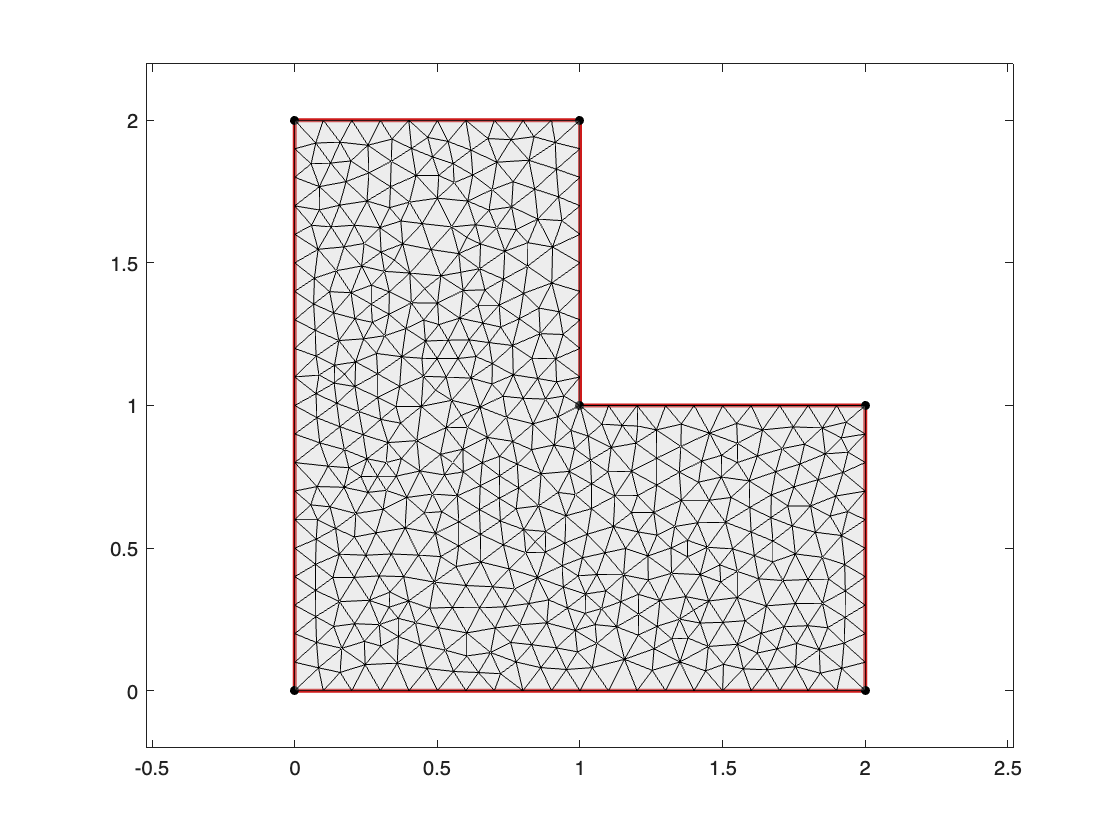

mesh.plot;

**Half-disc**

nodes = [-1 0; 1 0];
f = @(t) [cos(t) sin(t)];
edge1 = {1,2}; 
edge2 = {2,1,f,[0 pi]};
edges = {edge1,edge2};
domain = Domain(nodes,edges);
mesh = Mesh(domain,0.1);

building mesh
done


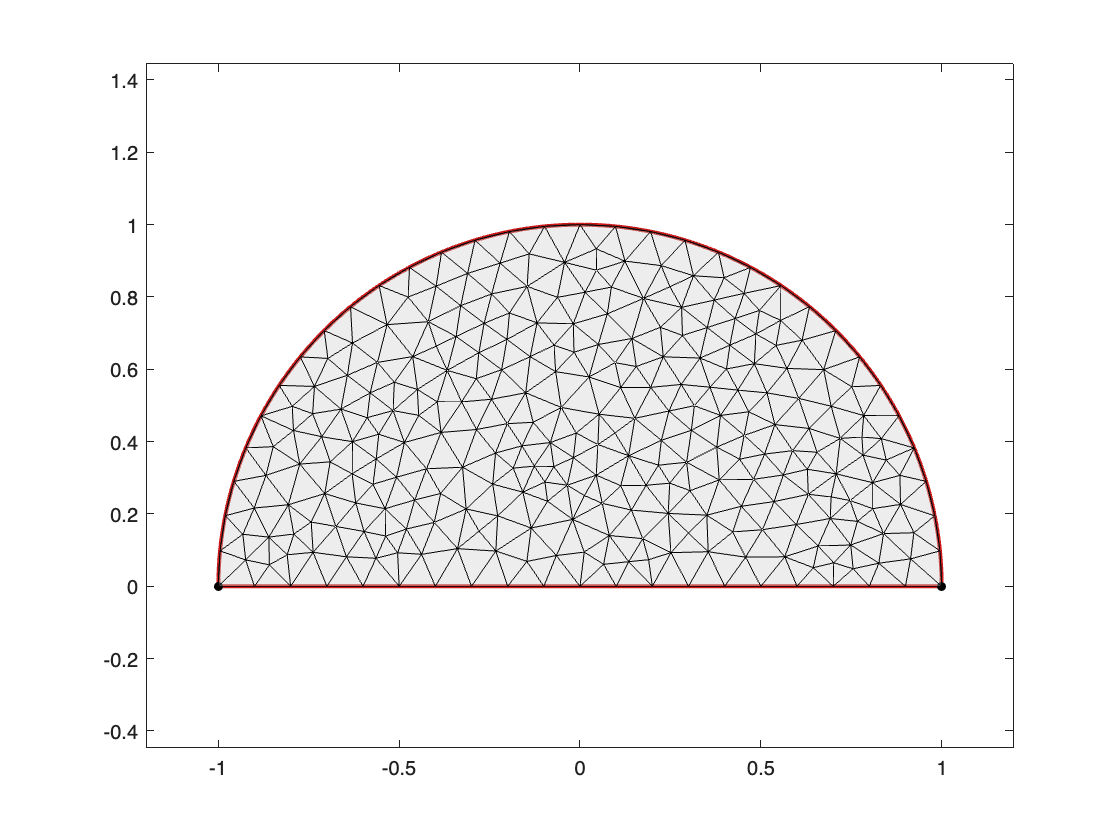

mesh.plot;

**Parabolic domain**

You can also use expressions depending on the parameter t. 

nodes = [0 0; 2 4;0 4];
edge1 = {1,2,{'t','t.^2'},[0,2]};
edge2 = {2,3};
edge3 = {3,1};
edges = {edge1,edge2,edge3};
domain = Domain(nodes,edges);

mesh = Mesh(domain,0.2);

building mesh
done


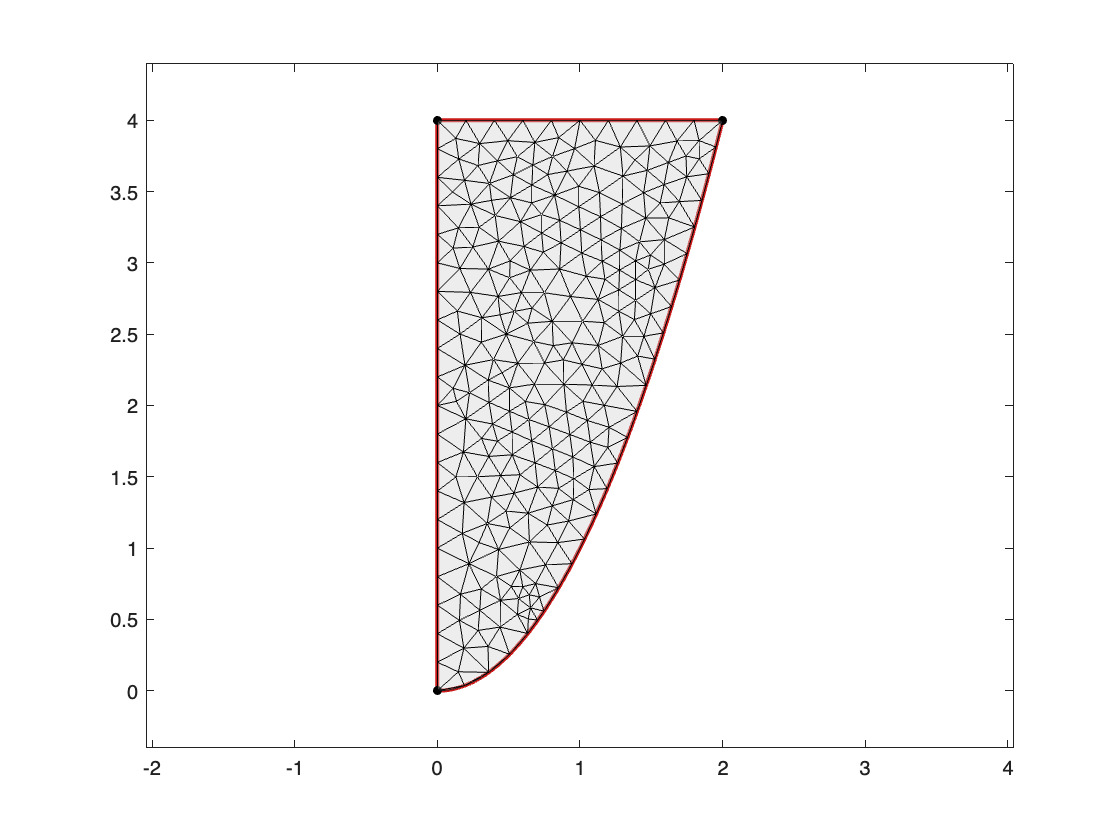

mesh.plot;

**Singular domains**

Outer singularity

nodes = [0 0; 1 -1/2; 1 1/2];
edges = {{1,2,'t','-t.^2/2',[0,1]}
         {2,3}
         {3,1,'t','t.^4/2',[1,0]}};
domain = Domain(nodes,edges);

mesh = Mesh(domain,0.05);

building mesh
done


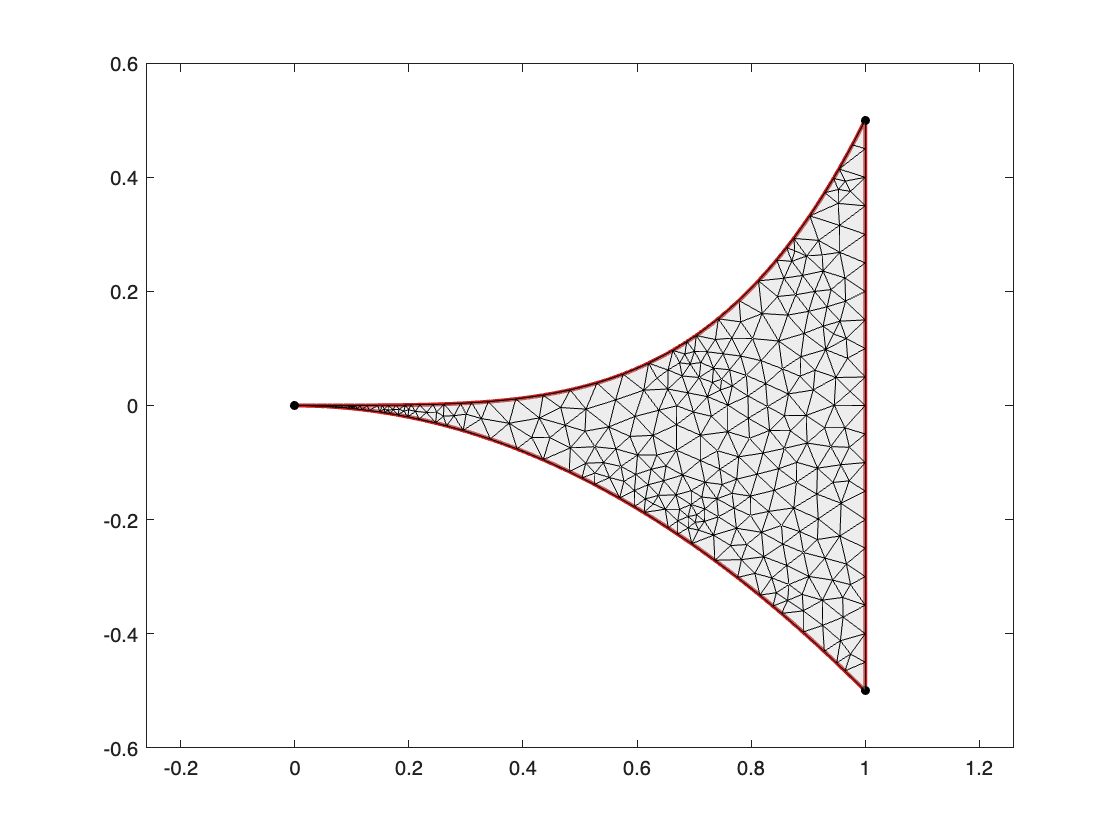

mesh.plot;

Inner singularity

nodes = [2 0 ; 0 0];

edge1 = {1,2,'cos(t).*(1+cos(t))', 'sin(t).*(1+cos(t))',[0 pi]};
edge2 = {2,1,'cos(t).*(1+cos(t))', 'sin(t).*(1+cos(t))',[pi 2*pi]};

domain = Domain(nodes,{edge1,edge2});

mesh = Mesh(domain,0.1);

building mesh
done


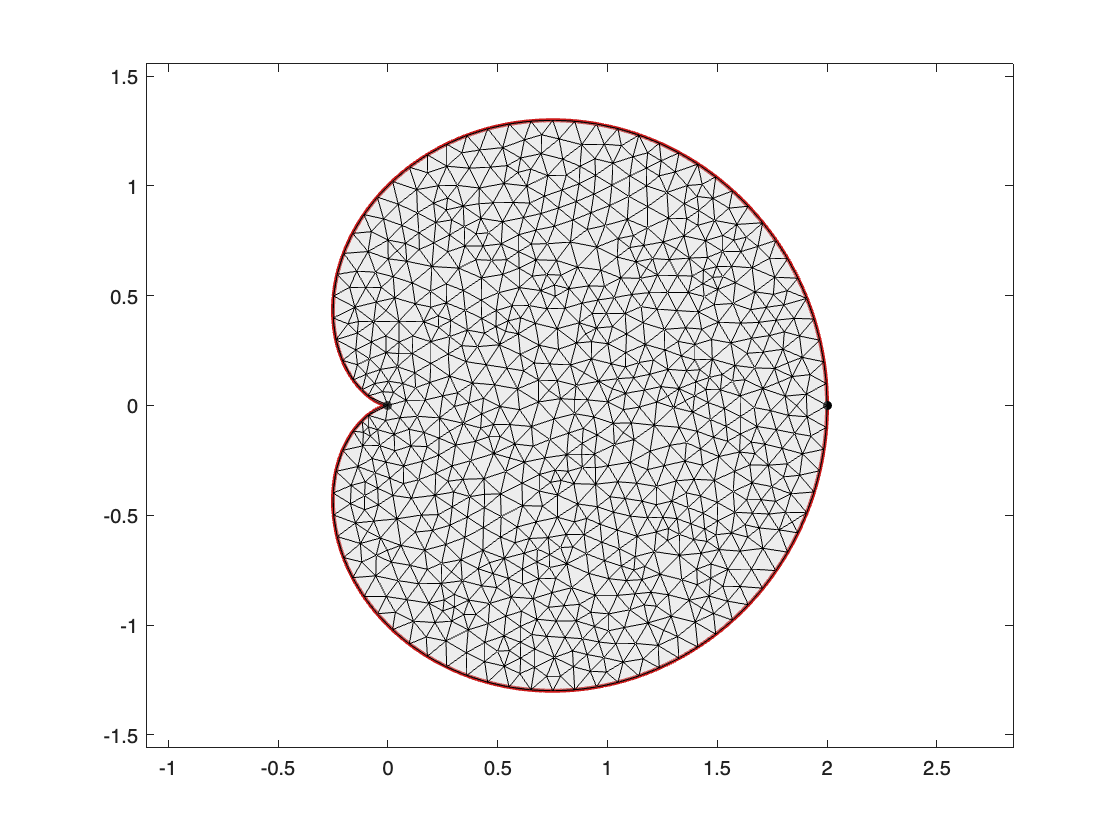

mesh.plot;

**Curved edges from intermediate edge nodes**

You can also define a curved edge using intermetiate edge nodes:

nodes = [0 0 ; 1 0 ; 1 1 ; 0 1];
enodes = [1 1; 0.75 1.3; 0.5 1.4; 0.25 1.3; 0 1];
edges = {{1,2};{2,3};{3,4,enodes};{4,1}};
domain = Domain(nodes,edges);
mesh = Mesh(domain,0.05);

building mesh
done


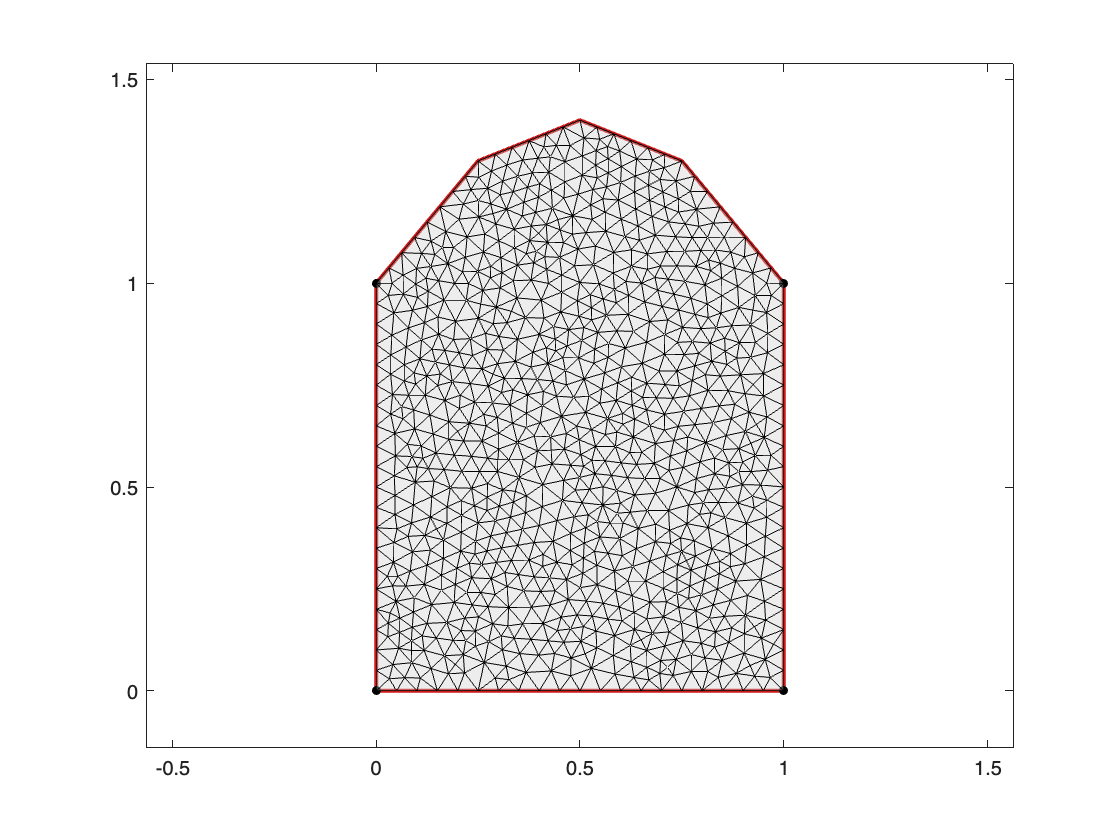

mesh.plot;

Similar to holes but we want now that the interior of the holes sto tay part of the domain. You just need to specify that the domain is both sides of the edges using the char parameter 'lr' or 'LR'. This kind of geometry will be used to generete a mesh inside and outside the inclusion. 

**Square with disc inclusion**

nodes = [-1 -1; 1 -1 ; 1 1; -1 1;0.5 0 ; -0.5 0];
edges = {{1,2}
         {2,3}
         {3,4}
         {4,1}
         {5,6,'0.5*cos(t)','0.5*sin(t)',[0,pi],'lr'}
         {6,5,'0.5*cos(t)','0.5*sin(t)',[pi,2*pi],'lr'}};
domain = Domain(nodes,edges);

mesh = Mesh(domain,0.1);

building mesh
done


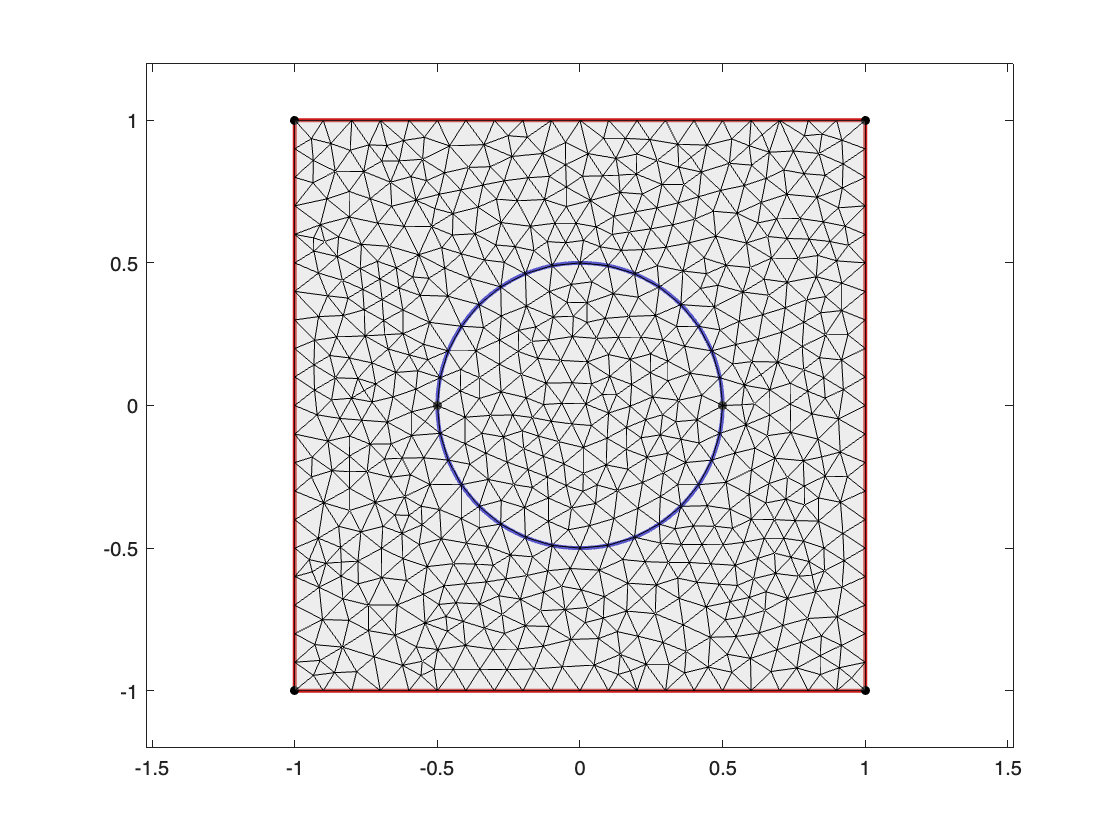

mesh.plot;

**Disc with cusp inclusion**

nodes = [1.5 0;0 0; 1 -1/2; 1 1/2];
edges = {{1,1,'1.5*cos(t)','1.5*sin(t)',[0,2*pi]}
         {2,3,'t','-t.^2/2',[0,1],'lr'}
         {3,4,'lr'}
         {4,1,'t','t.^4/2',[0,1],'lr'}};

domain = Domain(nodes,edges);

mesh = Mesh(domain,0.2);

building mesh
done


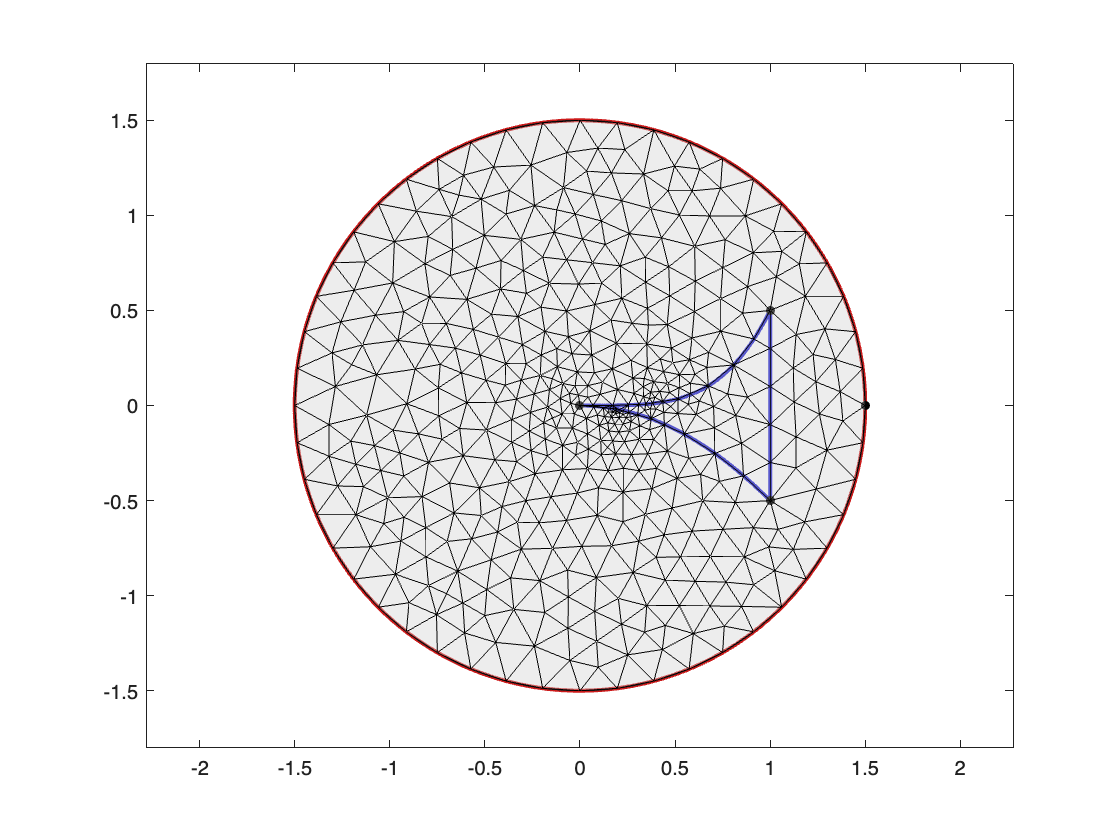

mesh.plot;

**Rectangle with internal egdges**

nodes = [-3 -1;3 -1;3 1;-3 1;-2,-1;-2,1;2,-1;2,1];
edges = {{1,2},{2,3},{3,4},{4,1},{5,6,'lr'},{7,8,'lr'}};

domain = Domain(nodes,edges);

mesh = Mesh(domain,0.2);

building mesh
done


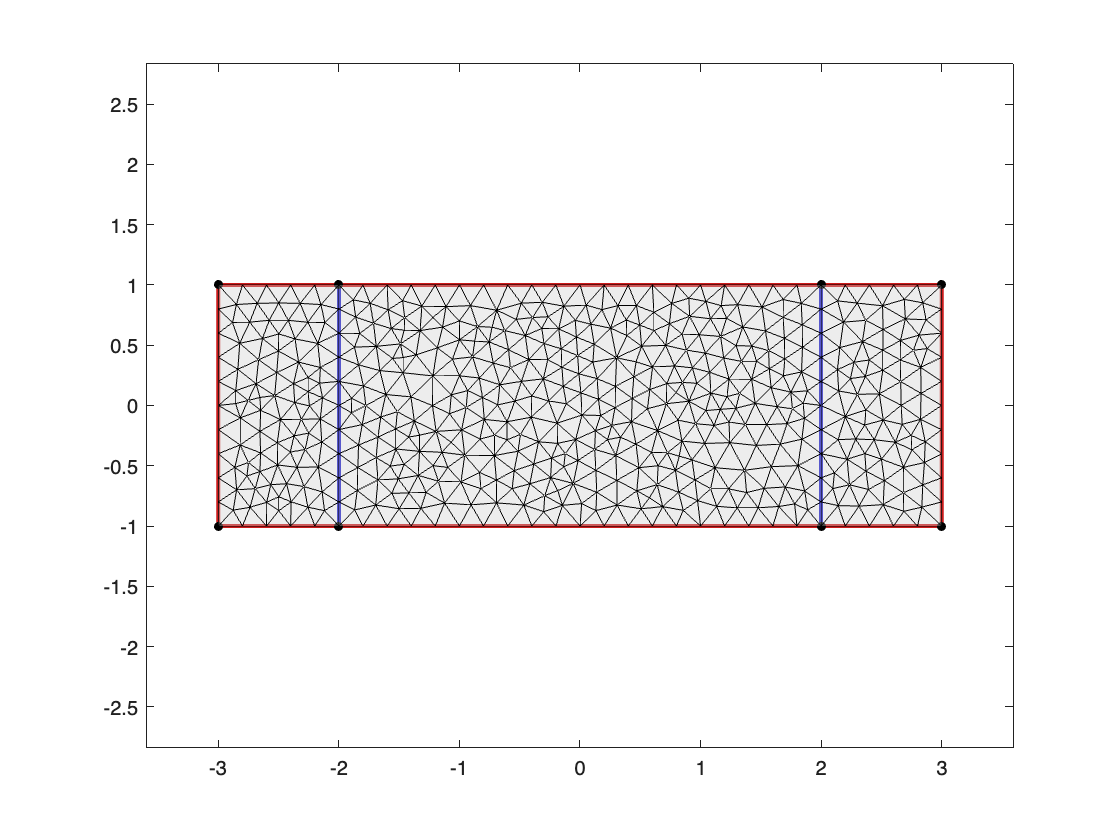

mesh.plot;

**Square domain with a circular hole**

nodes = [-1 -1; 1 -1 ; 1 1; -1 1;0.5 0];

edges = {{1,2}
         {2,3}
         {3,4}
         {4,1}
         {5,5,'0.5*cos(t)','0.5*sin(t)',[0,2*pi],'r'}};

domain = Domain(nodes,edges);

mesh = Mesh(domain,0.1);

building mesh
done


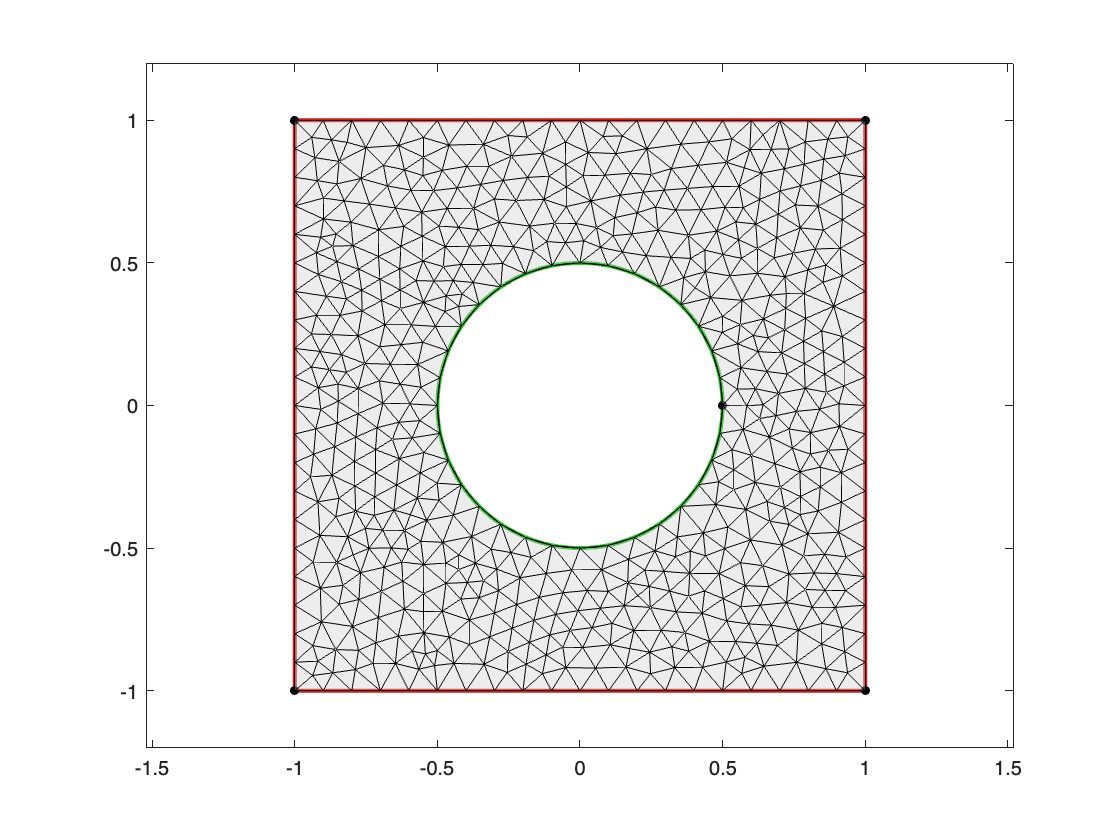

mesh.plot;

**Circular domain with a singular hole**

nodes = [1.5 0;0 0; 1 -1/2; 1 1/2];

edges = {{1,1,'1.5*cos(t)','1.5*sin(t)',[0,2*pi]}
         {2,3,'t','-t.^2/2',[0,1],'R'}
         {3,4,'r'}
         {4,2,'t','t.^4/2',[1,0],'R'}};

domain = Domain(nodes,edges);

mesh = Mesh(domain,0.1);

building mesh
done


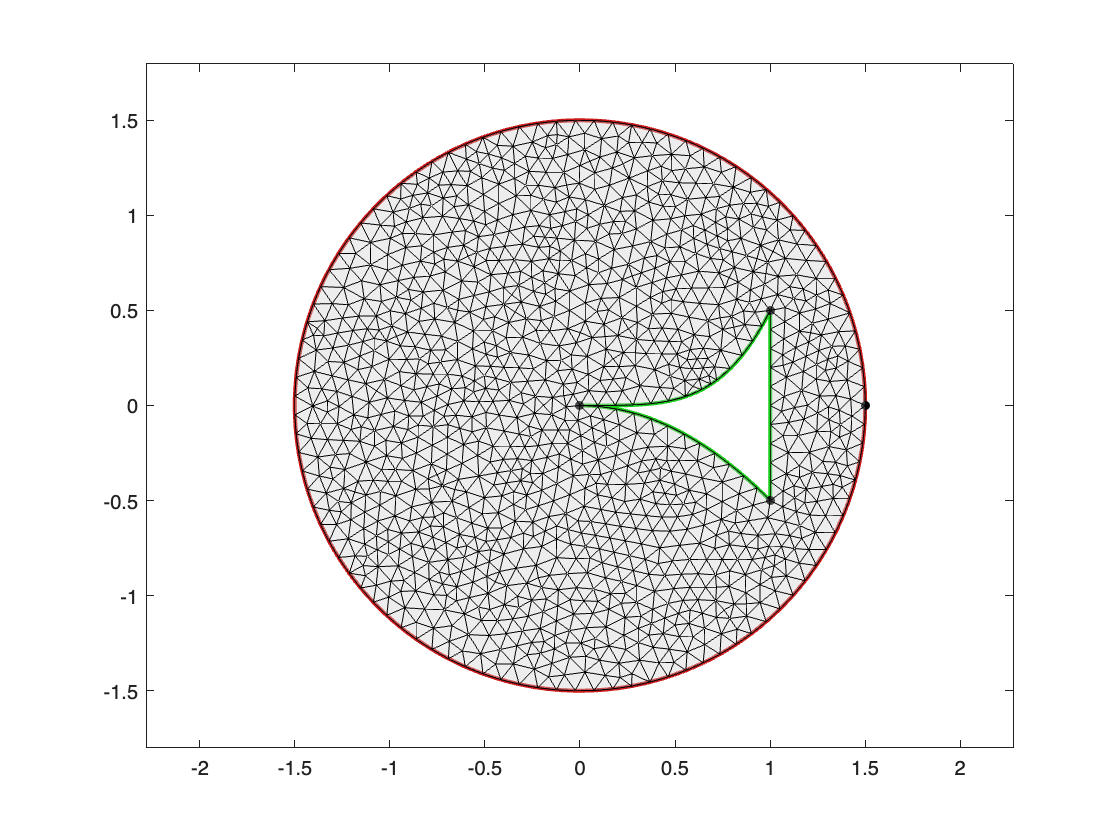

mesh.plot;

## 3. Mesh from a binary image

First get a binary image of your domain:

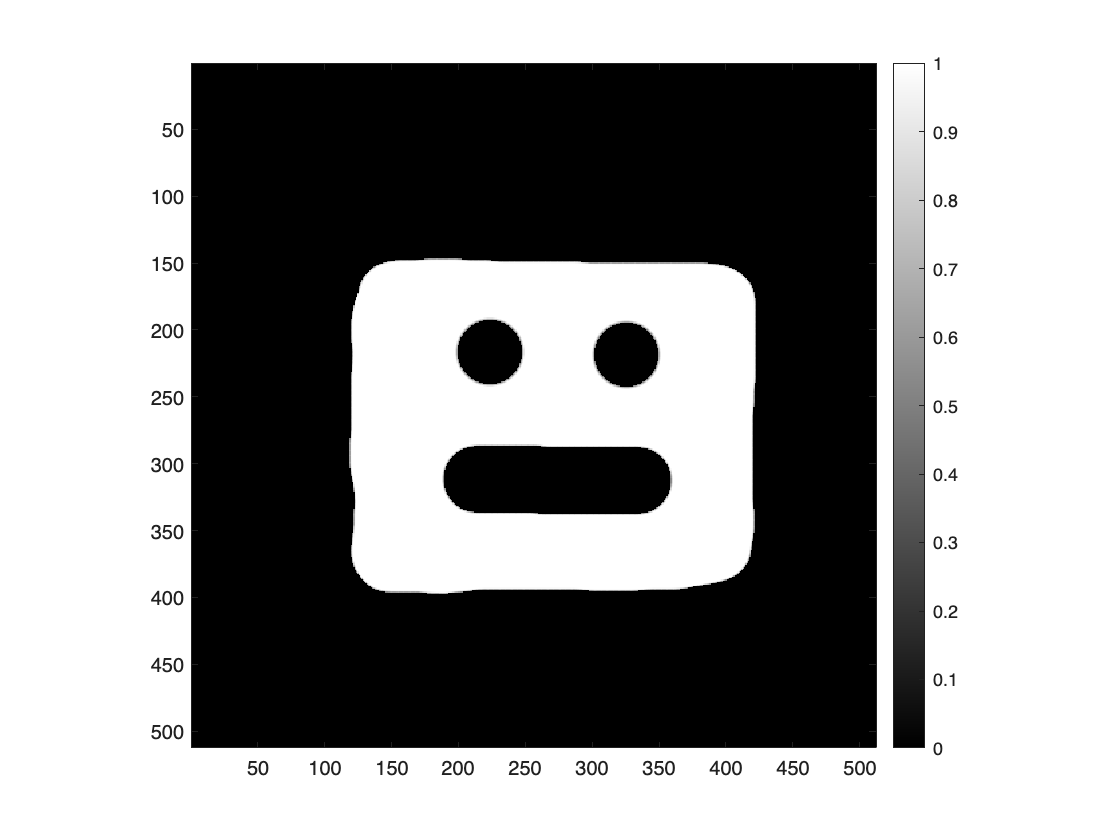

I = double(imread('face.png'));
I = sum(I,3)/3/255;
I(I<0.5) = 0;

imagesc(I);
colorbar;
axis image; colormap gray;

Then create the domain object:

domain = Domain('image',I,1/512);

then mesh it:

mesh = Mesh(domain,0.02);

building mesh
done


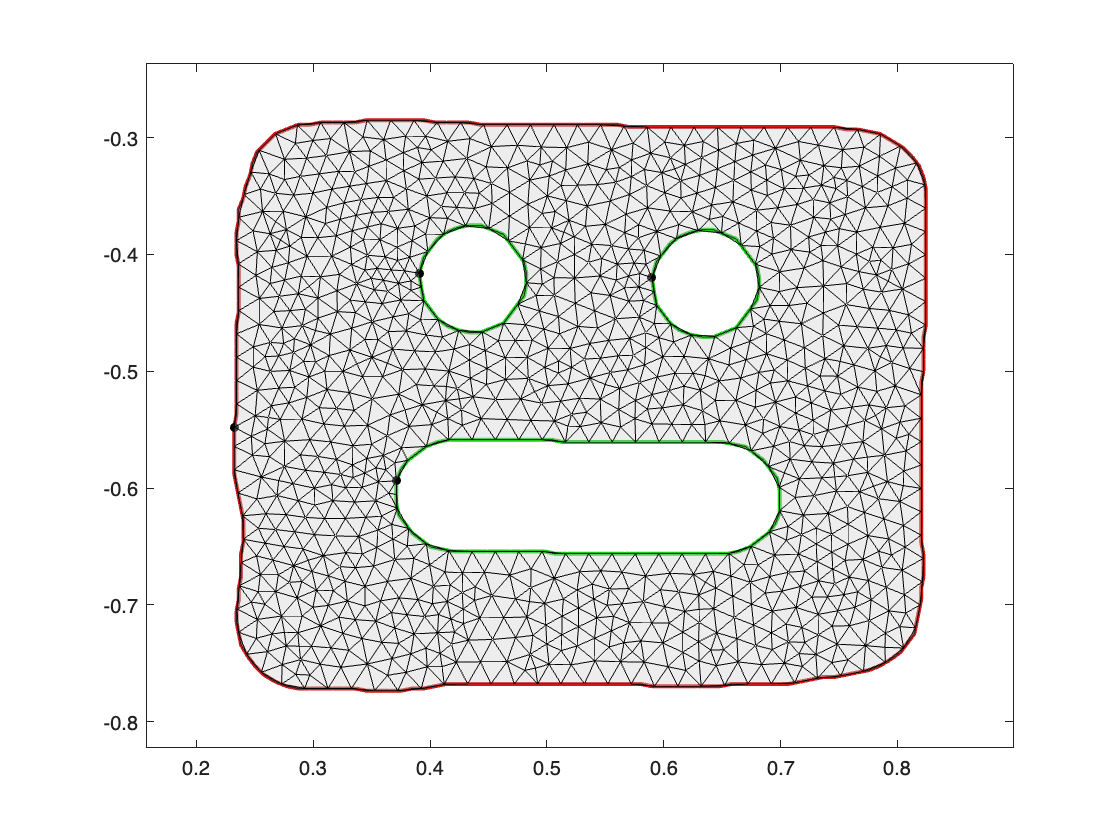

mesh.plot;

You can now create very complex domains such as the mediteranean sea with the main islands (undock the picture to see the details).

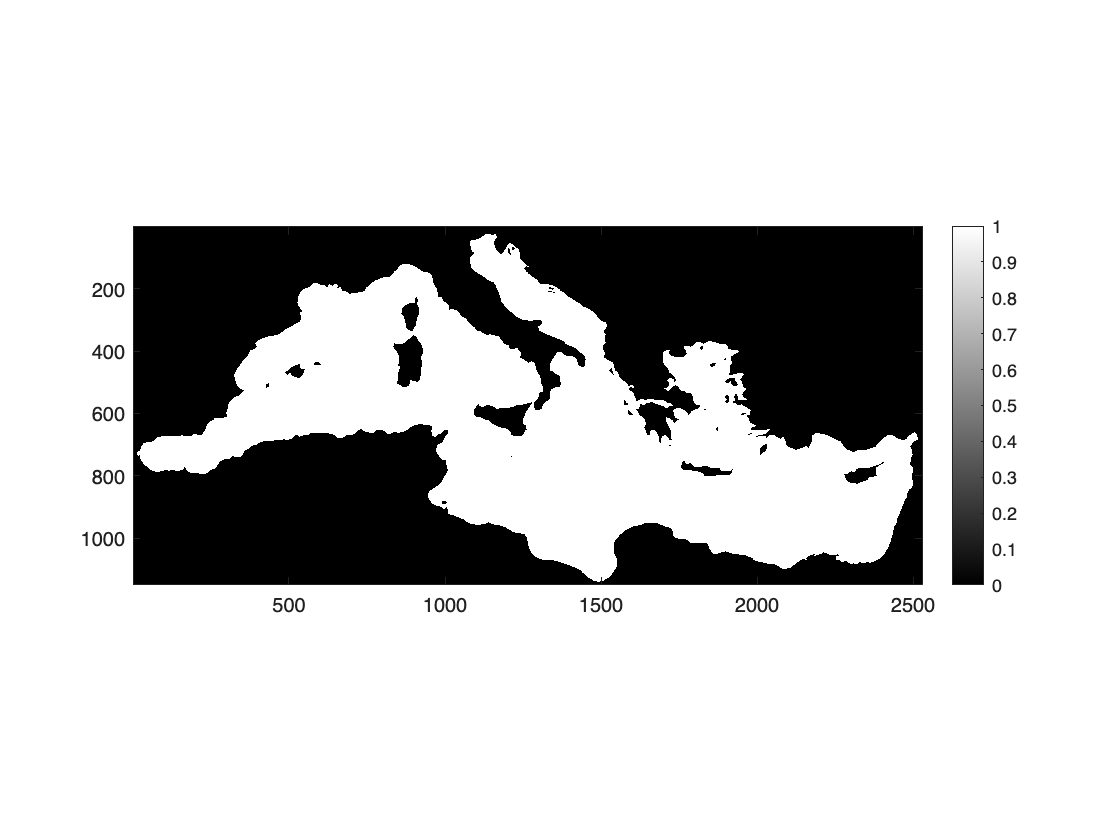

I = double(imread('mediteranee.png'));
imagesc(I);
colorbar;
axis image; colormap gray;

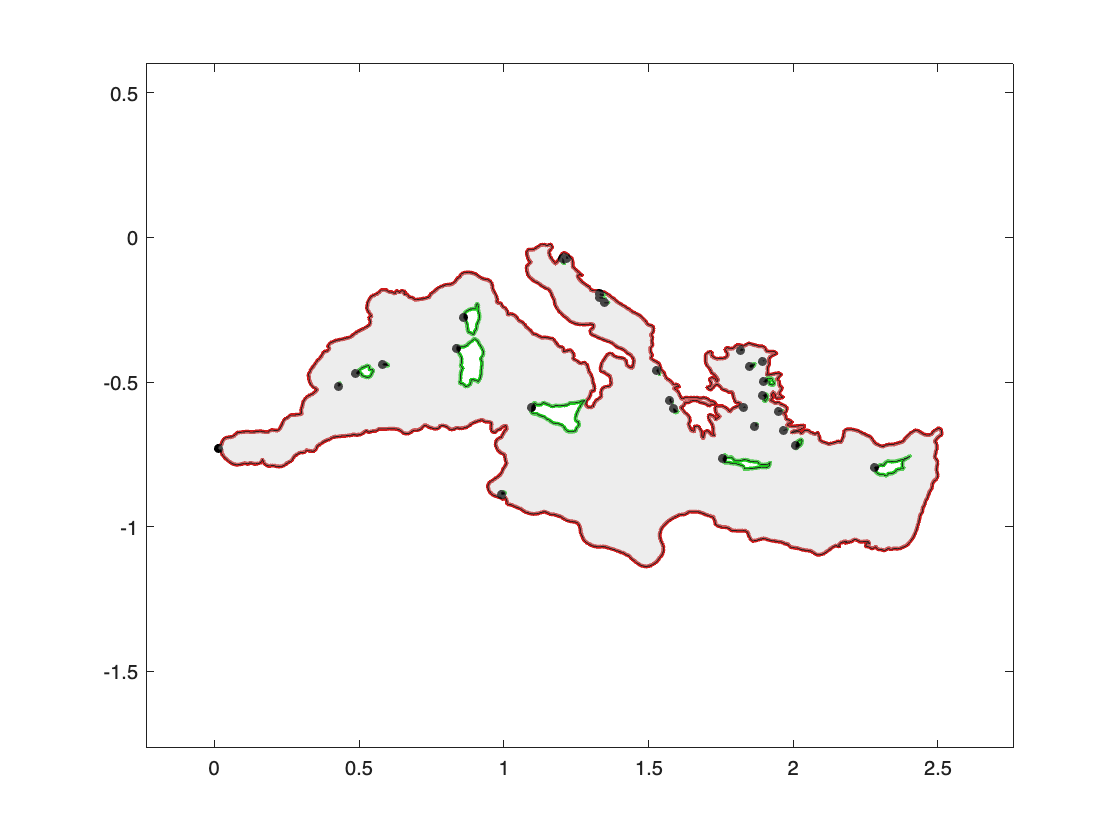

domain = Domain('image',I,1/1000);
domain.plot;

mesh = Mesh(domain,0.1,0.002);

building mesh
done


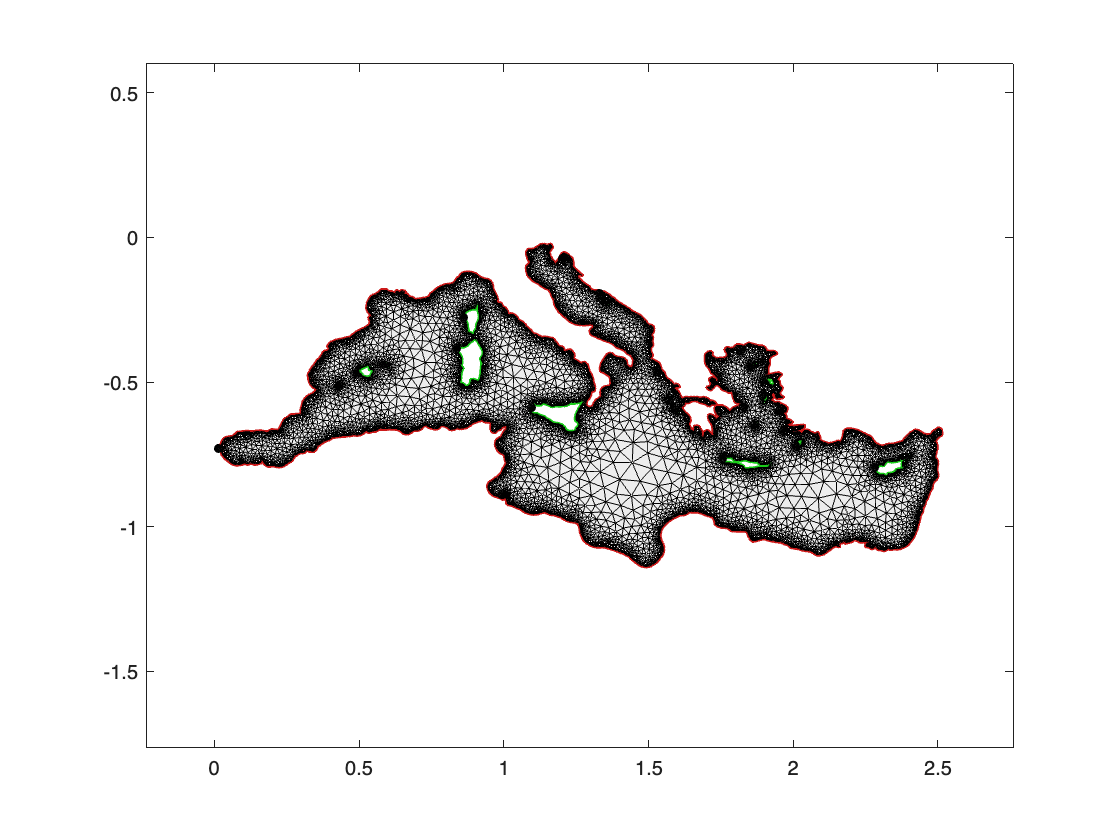

mesh.plot;